clear variables; close all; clc;

% Vehicle Position
lat = 40.6196; % [deg] latitude
lon = -74.1544; % [deg] longitude
alt_AGL = -11; % [m]
alt_MSL = 22; % [m]

[x, y, z] = latlon2cart(lat, lon)

x = 1.3219e+06

y = -4.6574e+06

z = 4.1524e+06

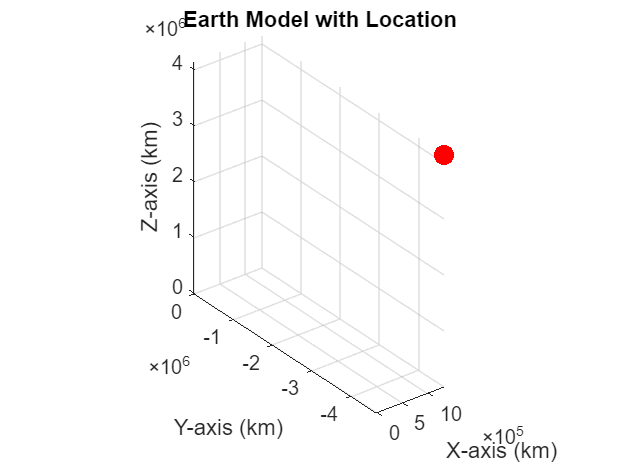

% Create a grid for the Earth sphere
theta = linspace(0, 2*pi, 100);
phi = linspace(0, pi, 50);

[theta, phi] = meshgrid(theta, phi);

% Convert spherical coordinates to Cartesian coordinates for the Earth sphere
earthRadius = 6371; % Earth radius in kilometers
x_earth = earthRadius * sin(phi) .* cos(theta);
y_earth = earthRadius * sin(phi) .* sin(theta);
z_earth = earthRadius * cos(phi);

% Plot the Earth sphere
figure;
surf(x_earth, y_earth, z_earth, 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.6);
hold on;
scatter3(x, y, z, 100, 'r', 'filled');
title('Earth Model with Location');
xlabel('X-axis (km)');
ylabel('Y-axis (km)');
zlabel('Z-axis (km)');
axis equal;
grid on;

hold off;

function [x, y, z] = latlon2cart(lat, lon)
    % Earth Constants
    radius = 6378137; % [m] radius of the earth

    % Convert latitude and longitude to radians
    lat = deg2rad(lat);
    lon = deg2rad(lon);

    % Calculate Cartesian coordinates
    x = radius * cos(lat) * cos(lon);
    y = radius * cos(lat) * sin(lon);
    z = radius * sin(lat);
end